Să se rezolve ecuația $f(x)=x^3-x-1=0$.

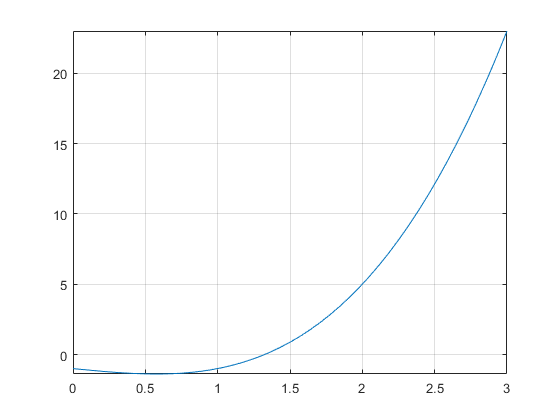

close all
f=@(x) x.^3-x-1;
fd=@(x) 3*x.^2-1;
fplot(f,[0,3]); grid on

Newton și secantă

x0=2; x1=1;
[z,ni]=Newton(f,fd,x0,1e-8)

z =    1.324717957244746


ni =      6


[z2,ni2]=secant(f,x0,x1,1e-8)

z2 =    1.324717957244714


ni2 =      7


Metoda aproximațiilor succesive

phi=@(x) (x+1).^(1/3);
[z,ni]=mas(phi,x0,1e-8)

z =    1.324717958582095


ni =     12


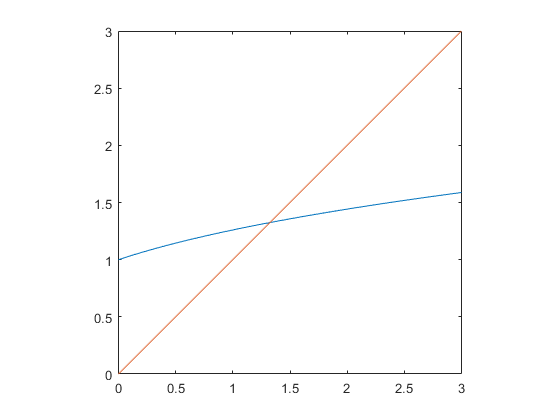

fplot(phi,[0,3]); hold on
plot([0,3],[0,3])
axis equal
hold off

Sistem neliniar

Vom exemplifica acum metoda lui Newton pentru un sistem $2\times 2$.


$$\begin{array}{l}
x_1^2 +x_2^2 -1=0\\
x_1^3 -x_2 =0
\end{array}$$


Geometric, prima ecuație reprezintă cercul unitate, iar a doua o parabolă cubică.

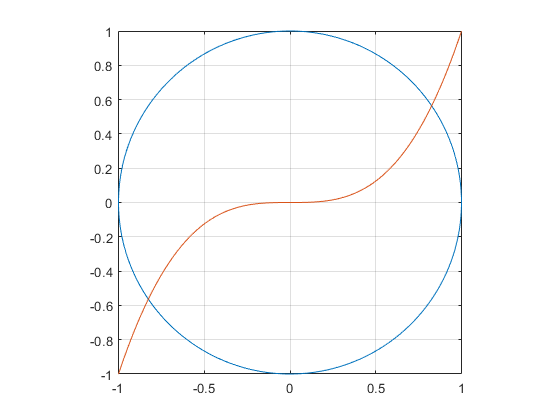

fimplicit(@(x,y) x.^2+y.^2-1,[-1,1]); hold on
fimplicit(@(x,y) x.^3-y,[-1,1])
axis equal; grid on
hold off

Definim funcția și jacobianul

F = @(x) [x(1)^2+x(2)^2-1; x(1)^3-x(2)];
dF = @(x) [2*x(1), 2*x(2); 3*x(1)^2, -1];

Rădăcinile sunt simetrice față de origine. O valoarea de pornire va fi $x_0=[1,1]^T$. Cu metoda lui Newton, obținem soluțiile

x0=[1;1]

x0 =      1
     1


[z1,ni1]=Newton(F,dF,x0,1e-8,1e-8,20)

z1 =    0.826031357654187
   0.563624162161259


ni1 =      5


[z2,ni2]=Newton(F,dF,-x0,1e-8,1e-8,20)

z2 =   -0.826031357654187
  -0.563624162161259


ni2 =      5
